clc;
clear;

% Define the file path
filePath = 'C:\Users\stefd\Downloads\EE\Module_6\Project\Chapter7\data_files\measurements_when_segway_stabilizes.csv';

% Read the CSV file into a table
data = readtable(filePath);

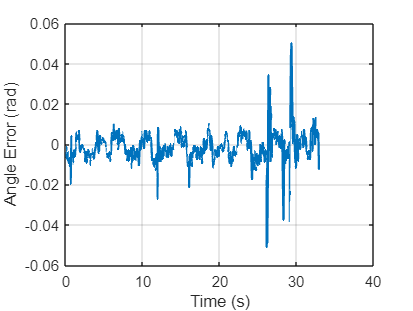


% Extract the variables
time = data.time;
angle = data.angle - 0.02; % Subtract 0.02 from angle
p_body = data.p_body;
p_wheel = data.p_wheel;

% Plot angle over time
figure;
plot(time, angle, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Angle Error (rad)');
grid on;

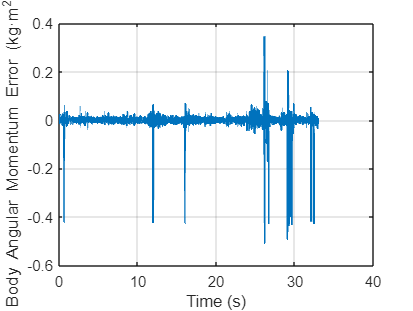


% Plot p_body over time
figure;
plot(time, p_body, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Body Angular Momentum Error (kg·m^2/s)');
grid on;

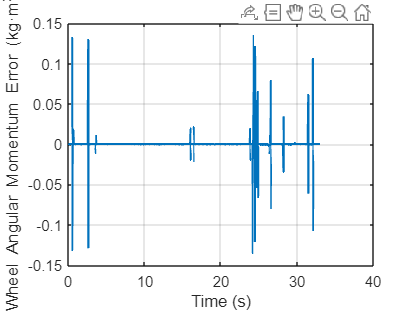


% Plot p_wheel over time
figure;
plot(time, p_wheel, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Wheel Angular Momentum Error (kg·m^2/s)');
grid on;